rosshutdown

Shutting down global node /matlab_global_node_86442 with NodeURI http://10.42.0.28:40209/


init_turtlebot_connection('10.42.0.1', '10.42.0.28')

Initializing global node /matlab_global_node_53119 with NodeURI http://10.42.0.28:41727/


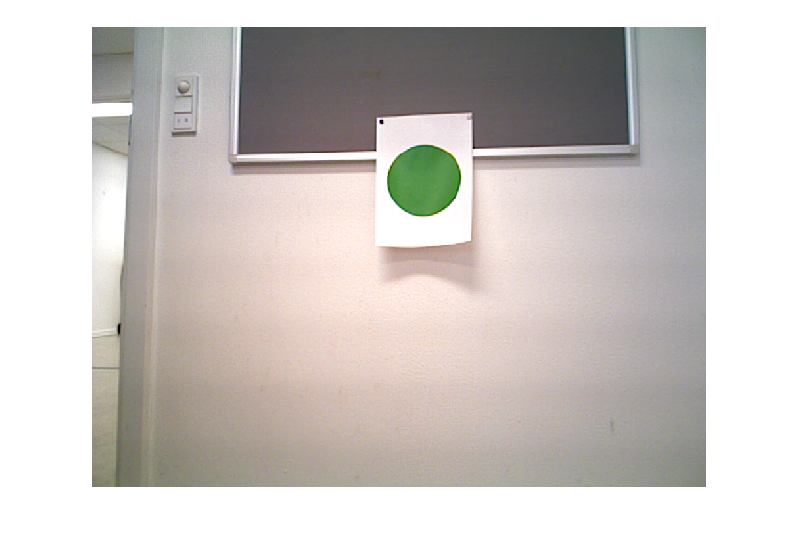

% Grap image from camera
if ismember('/camera/rgb/image_color/compressed',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_color/compressed');
end

if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

delta_r = 97;
z = 0.8;
delta_x = 0.168;
k= 461.9;

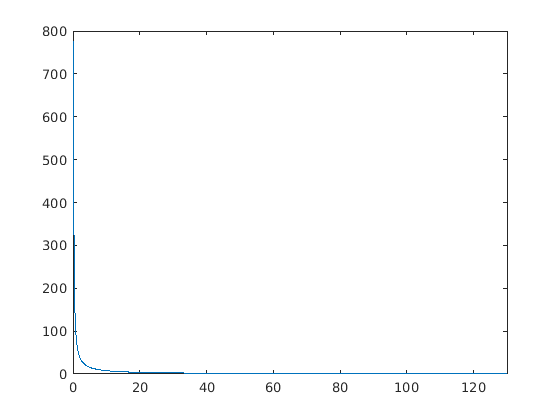

zaxis = (0:0.1:1000);
kdeltax = repmat(k*delta_x,1,10001);
r = kdeltax ./zaxis;
figure 
plot(zaxis,r)
xlim([0 130])

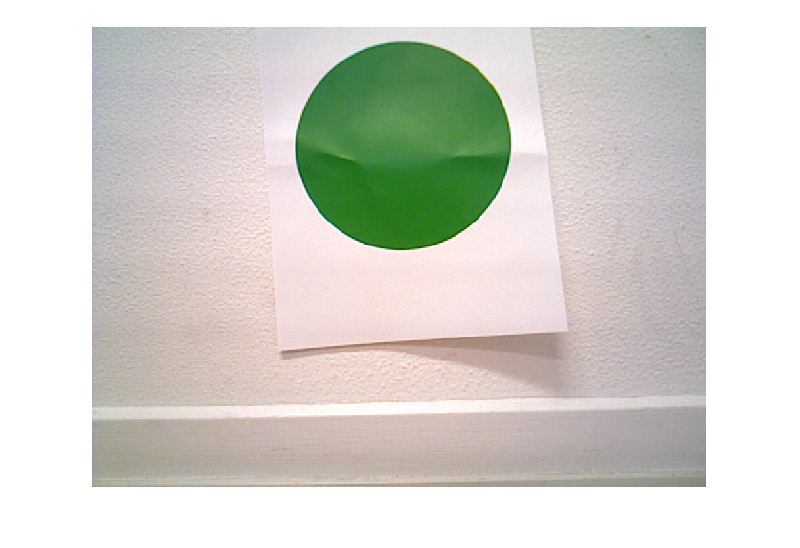



if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

hsv = rgb2hsv(img);
hue = hsv(:,:,1);
saturation = hsv(:,:,2);
value = hsv(:,:,3);

%Detect shape

satur_bin = saturation > 0.35;
kernel = ones(3,3);

satur_erode = imerode(satur_bin,kernel)

'imerode' requires Image Processing Toolbox.


%Measure shape

%Detect color of shape

imshow(satur_erode)